# Analisi Algoritmo di Bisezione 

In questa documentazione si mostreranno i casi di test relativi all'algoritmo di bisezione.

# Test di accuratezza

Il  test di accuratezza determina quanto la soluzione approssimata trovata attraverso il metodo di bisezione si avvicina alla soluzione dell'algoritmo* fzero()*. Quest'ultimo è il migliore algoritmo utilizzato per trovare lo zero di una funzione in Matlab. Ai fini del calcolo dell' accuratezza è stata implementata la funzione *CalcoloAccuratezza()* . Essa calcola l'errore relativo tra le soluzioni restituite dai due algoritmi al medesimo problema. 

## **Esempio**

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.

`Command line Matlab`

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];

CalcoloAccuratezza(f,x0,1e-10)

ans = 4.5544e-11

CalcoloAccuratezza(f,x0,1e-11)

ans = 1.7684e-12

CalcoloAccuratezza(f,x0,1e-12)

ans = 3.7669e-13

CalcoloAccuratezza(f,x0,1e-13)

ans = 2.2651e-16

CalcoloAccuratezza(f,x0,1e-14)

ans = 2.2651e-16

CalcoloAccuratezza(f,x0,1e-15)

ans = 2.2651e-16

CalcoloAccuratezza(f,x0,eps)

ans = 2.2651e-16

`Esecuzione da interfaccia grafica`

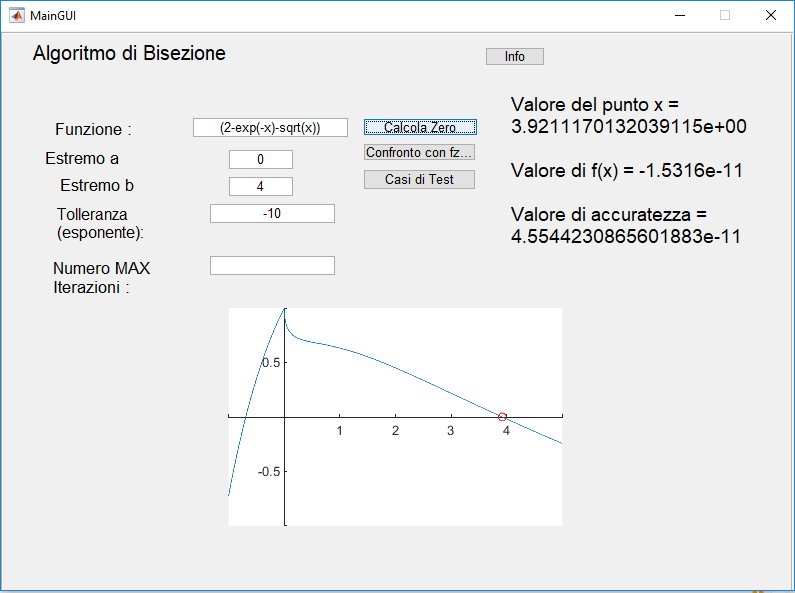

# Valutazione Performance

Si è implementata una funzione che crea un grafico di confronto tra i due algoritmi sopra citati. Si è calcolata la performance confrontando il numero di iterazioni necessarie all'algoritmo di Bisezione con quelle necessarie alla funzione fzero() considerata la tolleranza richiesta. 

## **Esempio**

Calcola la performance dell'algoritmo di bisezione quando è in input la funzione $\mathrm{sin}\left(x\right)+\mathrm{cos}\left(x\right)-x^{2\text{ }} +4$ nell'intervallo $\left\lbrack 0,2\pi \right\rbrack \ldotp$ Ciò viene calcolato al variare della tolleranza TOL inserita dall'utente e supponendo NMAX di default. La funzione restituirà un grafico di confronto tra i due approcci.

`Command line Matlab`

warning('off');
warning;

All warnings have the state 'off'.


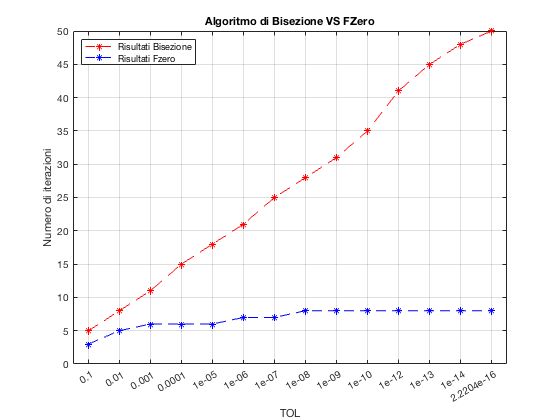

f = @(x) (sin(x)+cos(x)-x.^2+4);%funzione handle
xo = [0 2*pi];
%Vettore di tolleranze da 10^-1 sino a eps
TOL=[10.^-1 10.^-2 10.^-3  10.^-4 10.^-5 10.^-6 10.^-7 10.^-8 10.^-9 10.^-10 10.^-12                                                                                             10.^-13 10.^-14 eps];
Valuta_Performance(f,x0,TOL);

`Esecuzione da interfaccia grafica`

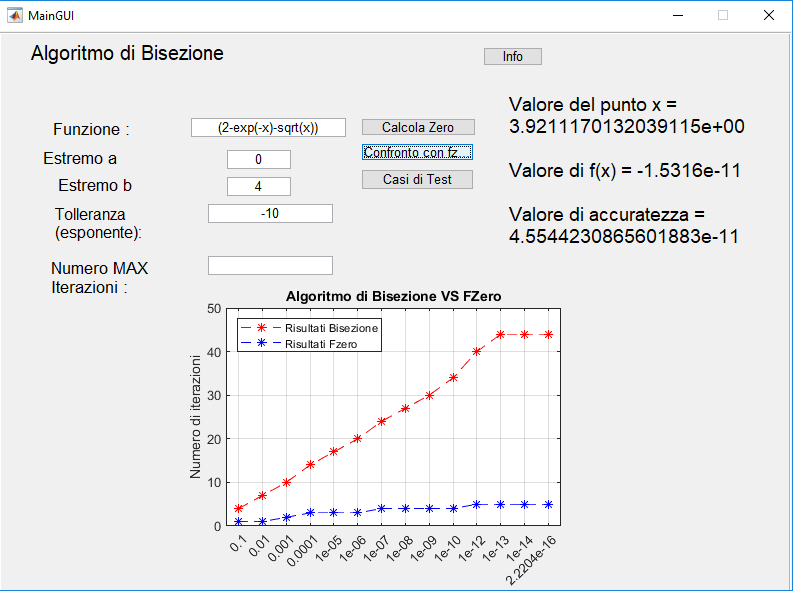

Come si nota dal grafico il numero di iterazioni richieste dalla funzione fzero() è minore rispetto a quelle della funzione algoritmo_di_bisezione() per ogni valore di TOL. Si può osservare che la differenza tra i due approcci è tanto più marcata quanto più si cerca una risoluzione migliore diminuendo la tolleranza.

# Test di robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 15 ,implementati in una classe definita dal matlab *matlab.unittest.TestCase*. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.

Di seguito seguono i casi di test più rilevanti che sono stati effettuati.

## Test case 2

 Verifica l'errore nel caso in cui il valore della funzione non sia handle.

## Input


$$\begin{array}{l}
f=\prime a^{\prime } \\
\mathrm{x0}=\left\lbrack 0\;4\right\rbrack \\
\mathrm{TOL}={10}^{-15} \\
\mathrm{NMAX}=600
\end{array}$$


## Test case 4

 Verifica l'errore nel caso in cui il primo estremo o il secondo estremo dell'intervallo inserito non sia numero.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\text{x0}=\left\lbrack \mathrm{'a'}\text{ }4\right\rbrack \\
\text{TOL}={10}^{-15} \\
\text{NMAX}=600
\end{array}$$


## Test case 6

 Verifica l'errore nel caso in cui entrambi i valori dell'intervallo x0   siano uguali.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\mathrm{x0}=\left\lbrack 3\;3\right\rbrack \\
\mathrm{TOL}={10}^{-15} \\
\mathrm{NMAX}=600
\end{array}$$


## Test case 7

Verifica l'errore nel caso in cui non è soddisfatto il teorema degli zeri.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\mathrm{x0}=\left\lbrack -3\;3\right\rbrack \\
\mathrm{TOL}={10}^{-15} \\
\mathrm{NMAX}=600
\end{array}$$


## Test case 8

Verifica che la tolleranza sia stata inserita o meno dall'utente.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\mathrm{x0}=\left\lbrack 0\;4\right\rbrack \\
\mathrm{TOL}=\mathrm{non}\;\mathrm{inserito}\\
\mathrm{NMAX}=\mathrm{non}\;\mathrm{inserito}
\end{array}$$


## Test case 9

Si verifica se la tolleranza inserita è minore di eps.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\mathrm{x0}=\left\lbrack 0\;4\right\rbrack \\
\mathrm{TOL}=-1\\
\mathrm{NMAX}=600
\end{array}$$


## Test case 16

Verifica se l'accuratezza è adeguata  a partire da una determinata tolleranza TOL.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\mathrm{x0}=\left\lbrack 0\;4\right\rbrack \\
\mathrm{TOL}={10}^{-15} \\
\mathrm{NMAX}=600
\end{array}$$


## Test case 11

Verifica se il valore di NMAX  non è numerico, scalare,infinito oppure NaN.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\mathrm{x0}=\left\lbrack 0\;4\right\rbrack \\
\mathrm{TOL}={10}^{-15} \\
\mathrm{NMAX}=^{\prime } a^{\prime } 
\end{array}$$


## Caso di test 13                                                                                                                   

Verifica se il valore di NMAX è minore  2.

## Input


$$\begin{array}{l}
f=x^2 -4\\
\mathrm{x0}=\left\lbrack 0\;4\right\rbrack \\
\mathrm{TOL}={10}^{-15} \\
\mathrm{NMAX}=1
\end{array}$$


## Caso di test 15                                                                                                                      

 Verifica se si è superato il numero massimo di iterazioni per determinare l'uscita. Non sarà trovato lo zero.

## Input


$$\begin{array}{l}
f=2-e^{-x} -\sqrt{x}\\
\text{x0}=\left\lbrack 0\text{ }4\right\rbrack \\
\text{TOL}={10}^{-15} \\
\text{NMAX}=5
\end{array}$$


## Esecuzione  Test suite

Vengono effettuati i test a partire dagli input definiti in precedenza.

Running TEST_RICHIAMA_PARAMETRI
.......... ....

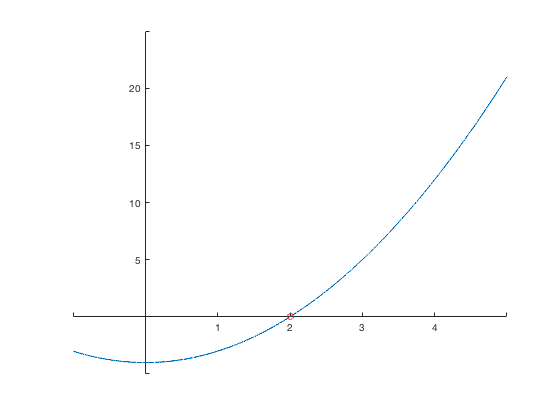

.
Done TEST_RICHIAMA_PARAMETRI
__________



result1 =   1×15 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   15 Passed, 0 Failed, 0 Incomplete.
   5.6743 seconds testing time.


result1 = runtests('TEST_RICHIAMA_PARAMETRI.m')

table(result1)

ans = 15×6 table
                    Name                    Passed    Failed    Incomplete    Duration       Details   
    ____________________________________    ______    ______    __________    _________    ____________

    'TEST_RICHIAMA_PARAMETRI/TestCase2'     true      false       false         0.42647    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase3'     true      false       false        0.034942    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase4'     true      false       false        0.029907    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase5'     true      false       false        0.022119    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase6'     true      false       false         0.07802    [1×1 struct]
    'TEST_RICHIAMA_PARAMETRI/TestCase7'     true  

## Riferimenti               

- Testing in Matlab: [https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html](https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**